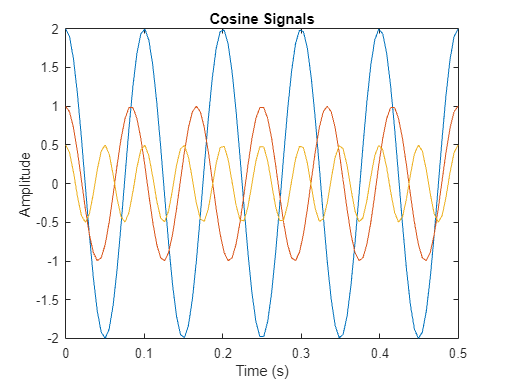


% Problem 1: Sampling and frequency-domain aliasing

x = 256;
a = 1 + mod(x, 3);

% Question 1:
% Generate time vector
t = linspace(0,1/a);  

% Generate the cosine signal
y1 = a*cos(2*pi*(5*a)*t);
y2 = (a/2)*cos(2*pi*(6*a)*t);
y3 = (a/4)*cos(2*pi*(10*a)*t);

% Plot the cosine signals
plot(t, y1);
hold on;
plot(t, y2);
hold on;
plot(t, y3);
hold off
xlabel('Time (s)');
ylabel('Amplitude');
title('Cosine Signals');

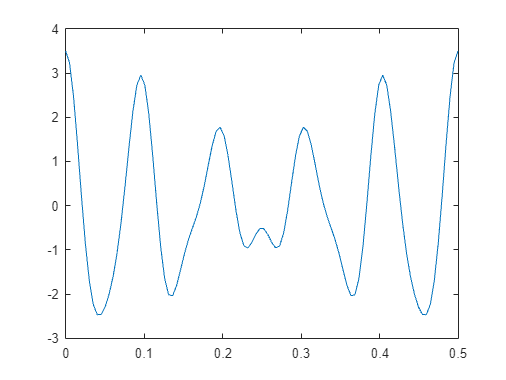


y=y1+y2+y3;
plot(t,y)

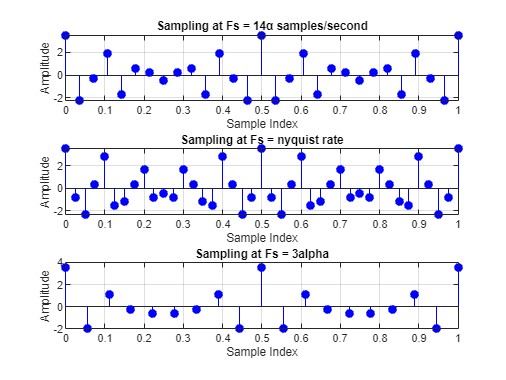


alpha =2;
duration = 1/alpha;
t = [0:0.0001:duration];

cumulative_waveform = alpha * cos(2 * pi * 5 * alpha * t) + ...
    (alpha/2) * cos(2 * pi * 6 * alpha * t) + ...
    (alpha/4) * cos(2 * pi * 10 * alpha * t);

Fs_a = 14 * alpha;
Fs_b = 2 * 10 * alpha;  % Nyquist rate
Fs_c = 9 * alpha;       % Aliasing rate

n_a = 0:1/Fs_a:1;
n_b = 0:1/Fs_b:1;
n_c = 0:1/Fs_c:1;

sampled_waveform_a = alpha * cos(2 * pi * 5 * alpha * n_a) + ...
    (alpha/2) * cos(2 * pi * 6 * alpha * n_a) + ...
    (alpha/4) * cos(2 * pi * 10 * alpha * n_a);

sampled_waveform_b = alpha * cos(2 * pi * 5 * alpha * n_b) + ...
    (alpha/2) * cos(2 * pi * 6 * alpha * n_b) + ...
    (alpha/4) * cos(2 * pi * 10 * alpha * n_b);

sampled_waveform_c = alpha * cos(2 * pi * 5 * alpha * n_c) + ...
    (alpha/2) * cos(2 * pi * 6 * alpha * n_c) + ...
    (alpha/4) * cos(2 * pi * 10 * alpha * n_c);

figure;

subplot(3, 1, 1);
stem(n_a, sampled_waveform_a, 'b', 'filled');
xlabel('Sample Index');
ylabel('Amplitude');
title('Sampling at Fs = 14α samples/second');
grid on;

subplot(3, 1, 2);
stem(n_b, sampled_waveform_b, 'b', 'filled');
xlabel('Sample Index');
ylabel('Amplitude');
title('Sampling at Fs = nyquist rate');
grid on;

subplot(3, 1, 3);
stem(n_c, sampled_waveform_c, 'b', 'filled');
xlabel('Sample Index');
ylabel('Amplitude');
title('Sampling at Fs = 3alpha');
grid on;

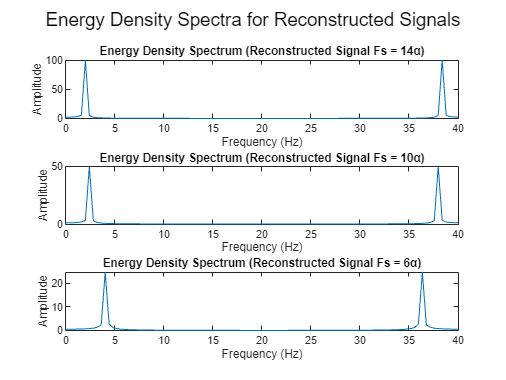

% Frequency domain representation using FFT
fft_reconstructed_a = fft(y1);
fft_reconstructed_b = fft(y2);
fft_reconstructed_c = fft(y3);

% Frequency values
frequencies_fft = linspace(0, Fs_b, length(fft_reconstructed_a));

% Plot energy density spectrum using FFT
figure;
subplot(3,1,1);
plot(frequencies_fft, abs(fft_reconstructed_a));
title('Energy Density Spectrum (Reconstructed Signal Fs = 14α)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

subplot(3,1,2);
plot(frequencies_fft, abs(fft_reconstructed_b));
title('Energy Density Spectrum (Reconstructed Signal Fs = 10α)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

subplot(3,1,3);
plot(frequencies_fft, abs(fft_reconstructed_c));
title('Energy Density Spectrum (Reconstructed Signal Fs = 6α)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

sgtitle('Energy Density Spectra for Reconstructed Signals');

% Define frequencies for "Do Re Mi Fa So La Ti Do"
frequencies = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 523.25]; % Frequencies in Hz
duration = 0.5; % Duration for each tone in seconds

% Generate the sequence
sequence = [];
for freq = frequencies
    t = 0:1/freq:duration;
    tone = sin(2*pi*freq*t);
    sequence = [sequence, tone];
end

% Normalize the sequence
sequence = sequence / max(abs(sequence));

% Different sampling rates
sampling_rates = [8000, 16000, 44100]; % Different sampling rates in Hz

for i = 1:length(sampling_rates)
    Fs = sampling_rates(i);
    filename = sprintf('sequence_%dHz.wav', Fs);
    
    % Save as a WAV file
    audiowrite(filename, sequence, Fs);
    
    % Listen to the audio
    fprintf('Listening to audio at %d Hz...\n', Fs);
    sound(sequence, Fs);
    pause(duration * length(frequencies) + 1); % Pause to listen to the entire sequence
end

Listening to audio at 8000 Hz...
Listening to audio at 16000 Hz...
Listening to audio at 44100 Hz...


t1=0:1/(14*a):1;
y1=a.*cos((2*pi*5*a).*t1);
y2=a/2.*cos((2*pi*6*a).*t1);
y3=a/4.*cos((2*pi*10*a).*t1);
Y1=y1+y2+y3;
subplot(3,1,1)
stem(Y1)
xlabel("t")
title("sampled at 14*a frequency")
t2=0:1/(20*a):1;
y1=a.*cos((2*pi*5*a).*t2);
y2=a/2.*cos((2*pi*6*a).*t2);
y3=a/4.*cos((2*pi*10*a).*t2);
Y2=y1+y2+y3;
subplot(3,1,2)
stem(Y2)
xlabel("t")
title("sampled at nyquist frequency")
t3=0:1/(4.5*a):1;
y1=a.*cos((2*pi*5*a).*t3);
y2=a/2.*cos((2*pi*6*a).*t3);
y3=a/4.*cos((2*pi*10*a).*t3);
Y3=y1+y2+y3;
subplot(3,1,3)
stem(Y3)
xlabel("t")
title("sampled at aliasing frequency")

%interpolation of the different signals with different sampling frequencies
figure
plot(t1,Y1,'o',t2,Y2,'-',t3,Y3,'--')

xlim([0.00 1.00])
ylim([-1.15 2.00])
title("interpolation of signals")
xlabel("t")

%Q5
notes=["Do" "Re" "Mi" "Fa" "So" "La" "Ti" "Do"];
freq=[261.6 293.6 329.6 349.2 392.0 440.0 493.8 523.25];

a=[];
for n=1:8
   t=0:0.000125:1; % Note duration
   a=[a sin(2*pi*freq(n)*t)]; % Signal
end

duration=10;
fs=[15000,20000,30000,40000,44100,50000];
for n=1:length(fs)
    sound(a,fs(n));
    pause(duration);
end    

% Saving as .wav file
Fs=44100;
filename="DoReMi.wav";
audiowrite(filename,a,Fs);

alpha =2

alpha = 2

freq_1 = 5 * alpha

freq_1 = 10

freq_2 = 6 * alpha

freq_2 = 12

freq_3 = 10 * alpha

freq_3 = 20


%sampling frequencies
Fs_a = 14 * alpha; % Fs = 14alpha samples/second
Fs_nyquist = 2 * max([freq_1, freq_2, freq_3]); % Nyquist rate
Fs_aliasing = 9 * alpha; % Aliasing scenario

signal_1 = alpha * cos(2 * pi * freq_1 * time);
signal_2 = (alpha / 2) * cos(2 * pi * freq_2 * t);
signal_3 = (alpha / 4) * cos(2 * pi * freq_3 * t);
signal_4 = signal_1 + signal_2 + signal_3;


% Sample the cumulative signal at different sampling frequencies
samples_a = signal_4(1 : round(Fs_a * duration) : end)

samples_a =     3.5000    3.4992    3.4966    3.4924    3.4865    3.4790    3.4698    3.4589    3.4463    3.4321    3.4163    3.3988    3.3798    3.3591    3.3368    3.3130    3.2876    3.2607    3.2322    3.2023    3.1709    3.1380    3.1037    3.0679    3.0308    2.9923    2.9525    2.9113    2.8689    2.8252    2.7803    2.7341    2.6869    2.6384    2.5889    2.5383    2.4867    2.4340    2.3804    2.3258    2.2703    2.2140    2.1568    2.0989    2.0401    1.9807    1.9205    1.8598    1.7984    1.7364


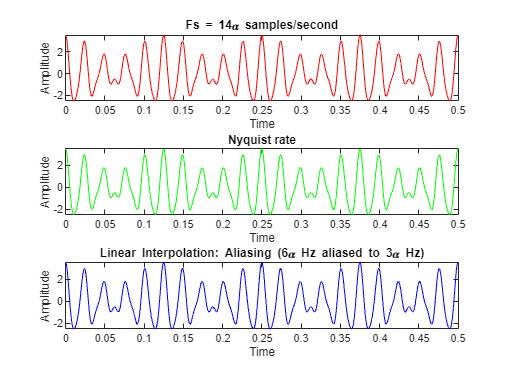

samples_nyquist = signal_4(1 : round(Fs_nyquist * duration) : end);
samples_aliasing = signal_4(1 : round(Fs_aliasing * duration) : end);

% Discrete-time waveforms using stem
time_a = linspace(0, duration, length(samples_a));
time_nyquist = linspace(0, duration, length(samples_nyquist));
time_aliasing = linspace(0, duration, length(samples_aliasing));

% Plot interpolated signals
figure;

subplot(3, 1, 1);
plot(time_a, samples_a, 'r');
title('Fs = 14\alpha samples/second');
xlabel('Time');
ylabel('Amplitude');


subplot(3, 1, 2);
plot(time_nyquist, samples_nyquist, 'g');
title('Nyquist rate');
xlabel('Time');
ylabel('Amplitude');


subplot(3, 1, 3);
plot(time_aliasing, samples_aliasing, 'b');
title('Linear Interpolation: Aliasing (6\alpha Hz aliased to 3\alpha Hz)');
xlabel('Time');
ylabel('Amplitude');